
cd('C:\Users\bgrau\GitHub\ieeg_affect\EEE\subjects\sub-03\ses-01')
clear all
load('stim_table_full.mat')
stim_table = movevars(stim_table, 'val_rating', 'After', 'cue_observed_mean');
stim_table = stim_table(:, [1:4 6:9 11 12 14 15 31 33]);
stim_table = sortrows(stim_table,"Pair","ascend");

cuehl = stim_table.highcue_indx;
cuemean = stim_table.cue_observed_mean;
pair = stim_table.Pair;
rating = stim_table.val_rating;
stimmean = stim_table.Valence_mean;


Total Effect Readout:


wh_high = cuehl > 0;
wh_low = cuehl < 0;

hi_table = stim_table(wh_high, :);
lo_table = stim_table(wh_low, :);


pair_table = table;
pair_table.pair_number = hi_table.Pair;
pair_table.hi_val = hi_table.val_rating;
pair_table.lo_val = lo_table.val_rating;
pair_table.rating_mean = (hi_table.val_rating + lo_table.val_rating)/2;
pair_table.cue_mean = (hi_table.cue_observed_mean + lo_table.cue_observed_mean)/2;
pair_table.cue_sd = (hi_table.cue_observed_std + lo_table.cue_observed_std)/2;
pair_table.stim_mean = (hi_table.Valence_mean + lo_table.Valence_mean)/2;
pair_table.stim_sd = (hi_table.Valence_SD + lo_table.Valence_SD)/2;
pair_table.rating_diff = hi_table.val_rating - lo_table.val_rating;
pair_table.stim_diff = (hi_table.Valence_mean - lo_table.Valence_mean);
d = pair_table.rating_diff;

% Two-tailed
[hyp, pval, ci, stat] = ttest(d);
fprintf('High vs. low cue effect: M = %3.2f, SE = %3.2f, t(%3.0f) = %3.2f, p = %3.6f\n', mean(d), ste(d), stat.df(1), stat.tstat(1), pval(1));

High vs. low cue effect: M = 0.39, SE = 0.22, t( 31) = 1.78, p = 0.084413


Cue Effect (ordered by pair number)

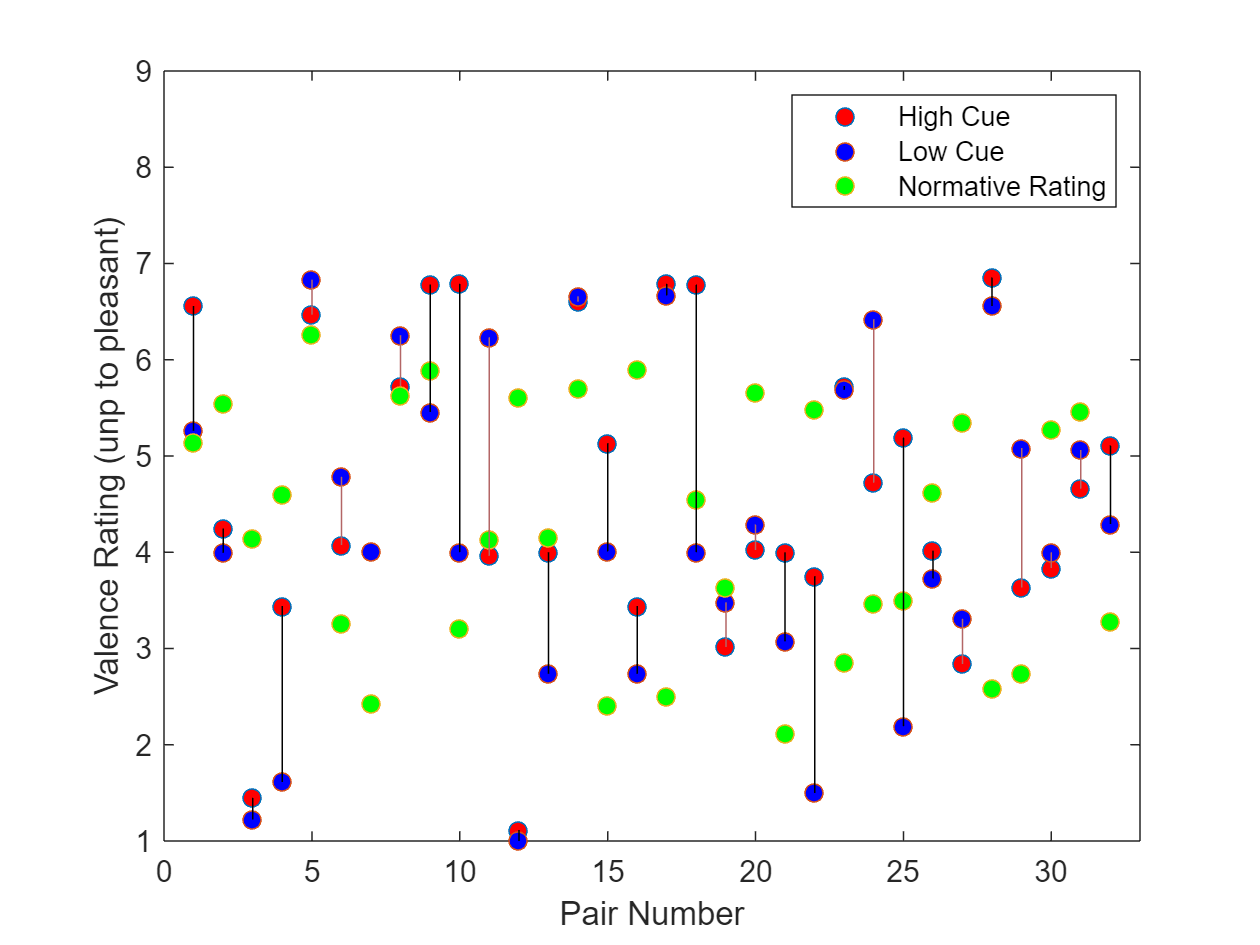

cuecolors = {[1 0 0] [0 0 1]};


y = [pair_table.hi_val pair_table.lo_val];  % ratings, [high low]
x = [pair_table.pair_number pair_table.pair_number];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');


d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

xlabel('Pair Number');
ylabel('Valence Rating (unp to pleasant)')

axis([0 33 1 9])
hold off;

legend([highdots lowdots meandots], {'High Cue', 'Low Cue', 'Normative Rating'})

I think that there's something interesting happening when individuals have strong pre-existing preferences for an image. I'll try to quantify that by looking at ratings that are more than 2 SD away from the normative mean. 

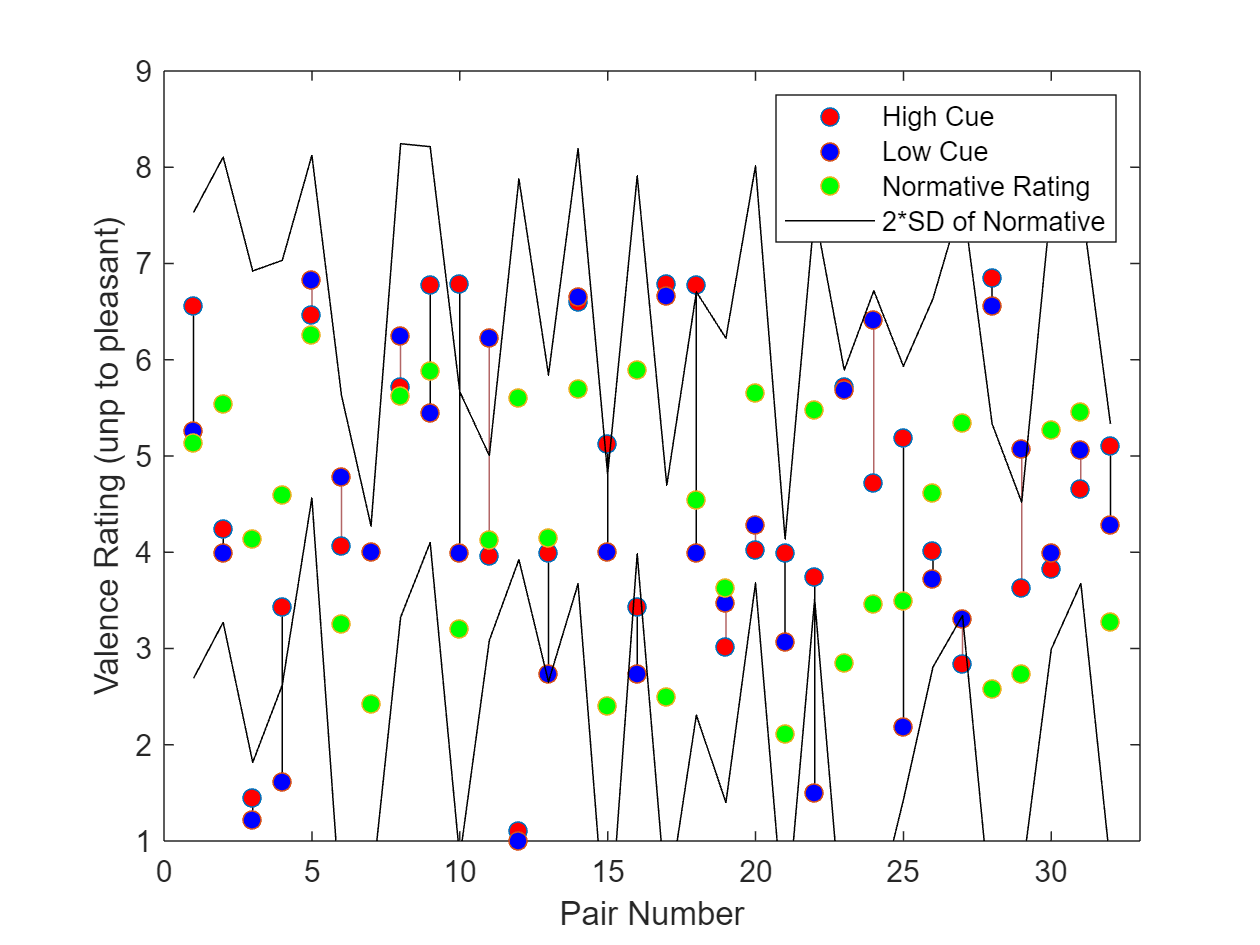

hi_sd = pair_table.stim_mean + (2*pair_table.stim_sd);
lo_sd = pair_table.stim_mean - (2*pair_table.stim_sd);
hold on;
highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');

sd_up = plot(hi_sd, 'k-');
sd_down = plot(lo_sd, 'k-');

xlabel('Pair Number');
ylabel('Valence Rating (unp to pleasant)')
hold off;
axis([0 33 1 9])
legend([highdots lowdots meandots sd_up], {'High Cue', 'Low Cue', 'Normative Rating', '2*SD of Normative'})

Cue Effect (ordered from largest to smallest)

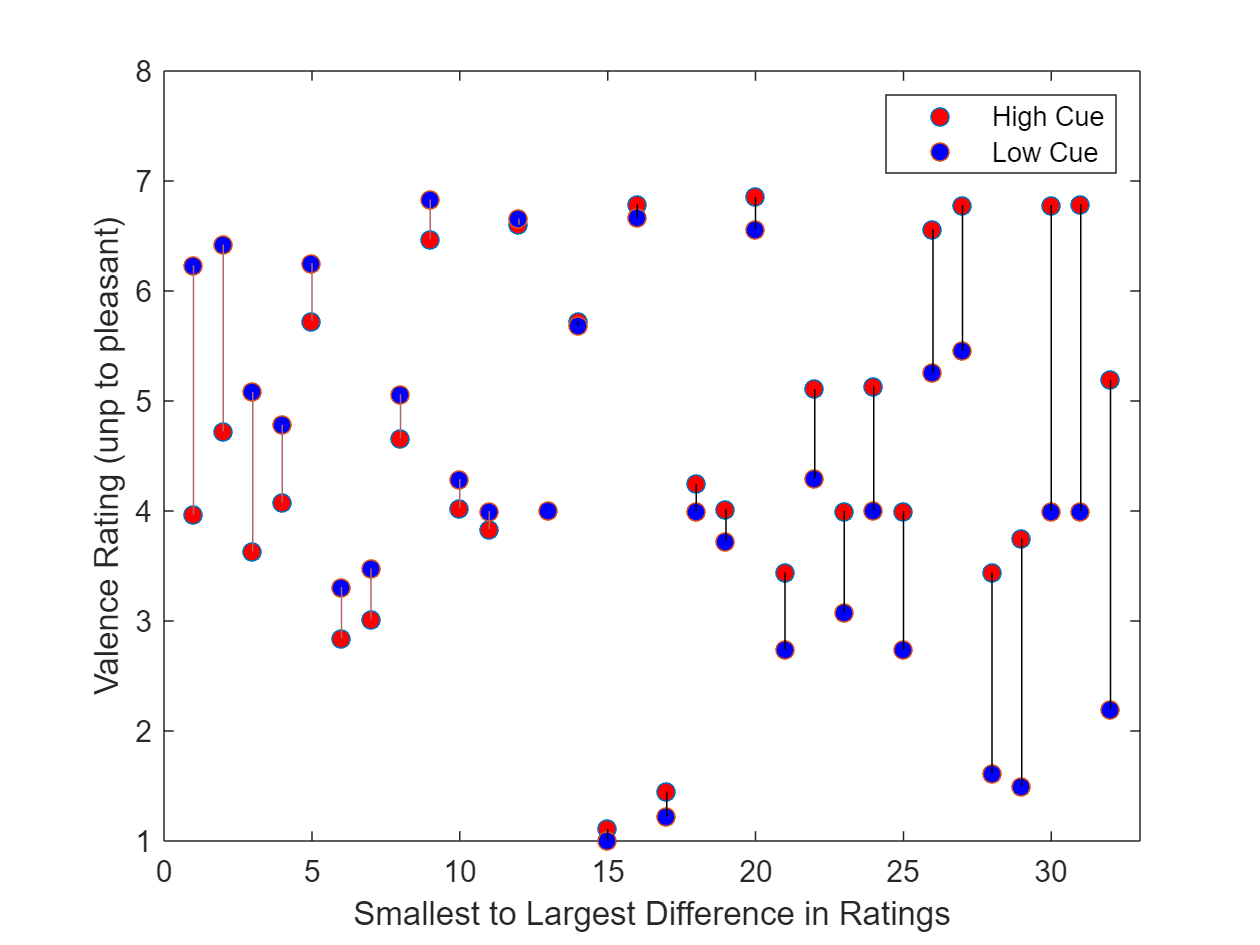

pair_table = sortrows(pair_table,"rating_diff","ascend");

pairs = [1:32]';

y = [pair_table.hi_val pair_table.lo_val];  % ratings, [high low]
x = [pairs pairs];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);


xlabel('Smallest to Largest Difference in Ratings');
ylabel('Valence Rating (unp to pleasant)')
hold off;

axis([0 33 1 8])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

Control of Cue Effect 

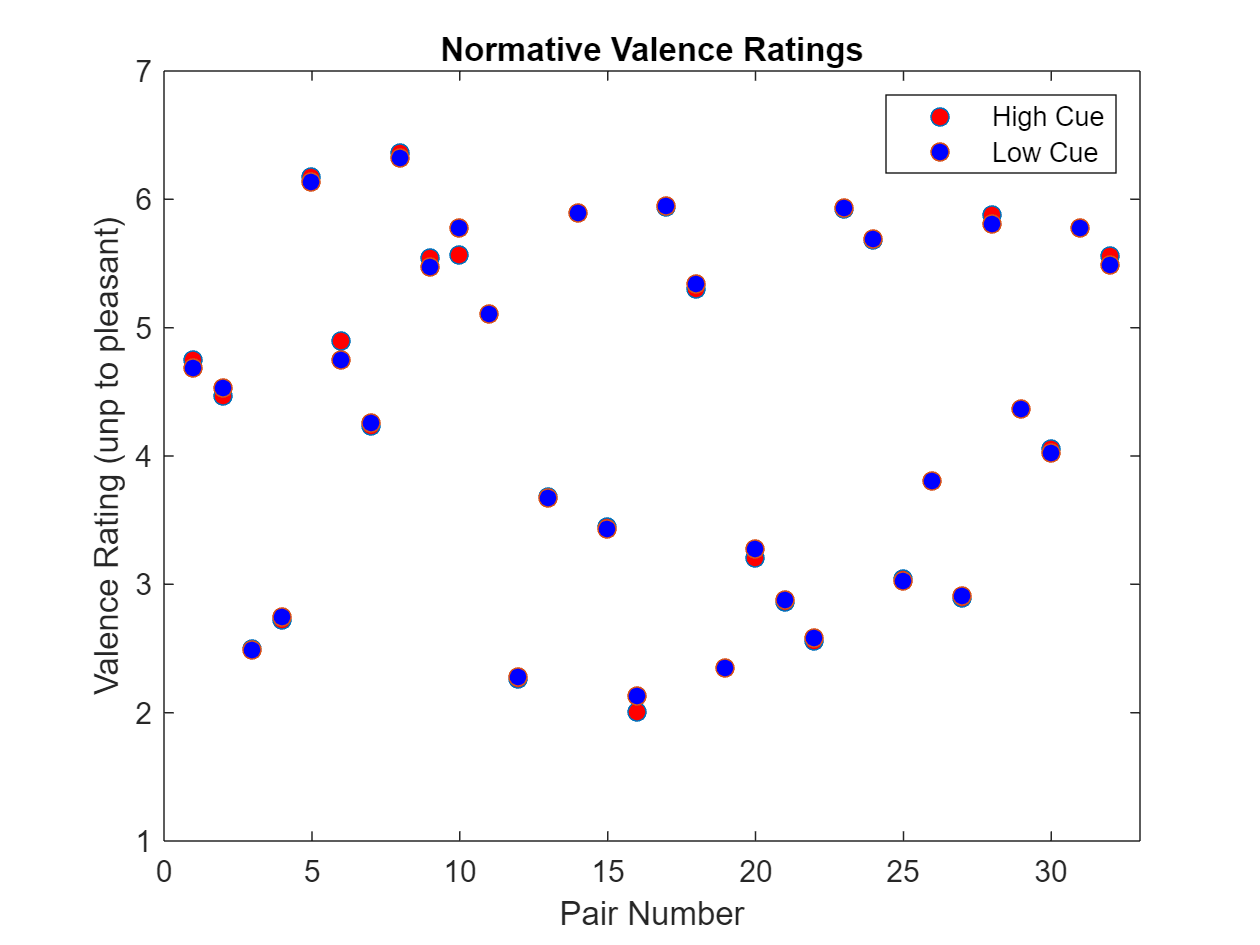



y = [hi_table.Valence_mean lo_table.Valence_mean];  % ratings, [high low]
x = [hi_table.Pair lo_table.Pair];  % pairs, [high low]

highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); hold off;

xlabel('Pair Number');
ylabel('Valence Rating (unp to pleasant)')
title('Normative Valence Ratings')

axis([0 33 1 7])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

Tor Comments on 5/4:

"... could generate our final plot and t-test for each subject, and also generate the same plot but order the pairs by size of the high-low cue effect.As a control, you could create the exact same plots but with NORMATIVE picture ratings for each pair. This would tell us whether there's a confound between experimentally randomized h and L cues and the normative ratings. Which there should not be.On tap for more sophisticated analyses:

- Model timeseries autocorrelation, potentially (probably rarely done in iEEG but rigorous), improving validity of P-values 

-     Try to model degree of picture independance

-     AR1 model in canlab tools ('glmfit general')

-     AR yeul (Yuel Walker equations)- whiten based on this removes autocorrelation. Maybe whiten whole set, then introduce pair info

(BEN NOTE: Not sure how to do this right now... will need to get the iEEG much cleaner.

- Control for normative picture ratings.  The simplest way is this: extract and save normative H cue - L cue picture rating diffs for each pair. This is what you need for the plot i suggested above. Then your paired t-test becomes a simple regression model: The outcome is difference scores H - L cue in actual patient ratings. The regression design matrix has an intercept and **mean-centered** H - L normative rating scores.  The effect of interest is the intercept term. That's the patient's average H - L cue effect controlling for variation in H - L cue effects in normative ratings (which should be small and random, as you randomly assigned H and L cues)."

- Check the sign test

- Look at correlations across time (find residuals from other model- maybe deviation from each pair)

Need regression model with normative image taken out, and has expectancy effect

Then correlate with self shifted in time. ARE ALL RATINGS INDEPENDANT?

% % Extract and compute normative H-L cue picture rating differences
normative_diff = pair_table.stim_diff;
% 
% Perform the regression model
X = [ones(size(normative_diff, 1), 1), normative_diff];
y = pair_table.rating_diff;
coeffs = regress(y, X);

% Extract the intercept term (effect of interest)
intercept = coeffs(1);

% Display the results
fprintf('Intercept (patient average H-L cue effect): %.4f\n', intercept);

Intercept (patient average H-L cue effect): 0.3855
